clc;clear;
addpath("ccdm\");addpath("Compute_fun\");addpath("mat_data\");

## **初始化一些参数**

设计一个概率成型的编码调制方案，使用LDPC编码，当调制阶数为n = log2(M)时，编码码率为R = n-2/n。

M = 64

M = 64

n = log2(M) 

n = 6

R = (n-2)/n

R = 0.6667

QAM由两路ASK信号构成,每路ASK信号独立同分布，根据文件名读取之前保存的分布

filename_bestP = ['best_P_',num2str(2^(n/2)),'ASK.mat'];
load(filename_bestP);
showsnr = 11%滑动滑块可以显示不同信噪比下的最优M-B分布

showsnr = 11

titlestring = [num2str(M),'QAM在',num2str(showsnr-1),'dB下的M-B分布']

titlestring = '64QAM在10dB下的M-B分布'

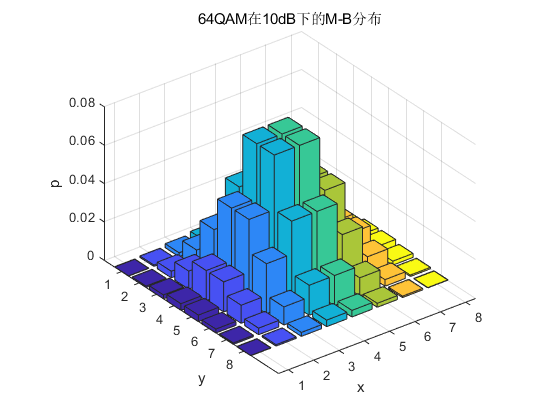

bar3(PX(showsnr,:)'*PX(showsnr,:));xlabel('x');ylabel('y');zlabel('p');title(titlestring)

每路LDPC编码长度为64800

snr = 0:1:25;     %信噪比
LDPC_bitlength = 64800;
n_ASK = LDPC_bitlength*2/n;  %ASK信号的长度
H = dvbs2ldpc(R);            %LDPC的H矩阵 

初始化LDPC编解码函数

ldpcEncoder = comm.LDPCEncoder(p);
ldpcDecoder = comm.LDPCDecoder(p);

仿真环节

for ii = 1:length(snr)
    best_P = PX(ii,:);
    
end